## 3.4 Eigenfunctions of Discrete-Time LTI Systems

This exercise examines the eigenfunction property of discrete-time LTI systems. Complex exponentials are eigenfunctions of LTI systems, i.e., when the input sequence is a complex

exponential, the output is the same complex exponential only scaled in amplitude by a complex constant. This constant can be computed from the impulse response h[n]. When

the input to a discrete-time LTI system is $x[n]=z^n$, the output is $y[n]=H(z)z^n$ an, where

                                                    
$$H(z)= \sum_{n=-\infty}^{\infty} h[n]z^{-n}$$


Consider each of the following input signals:

                                                    
$$x_1[n] = e^{ j (\pi/4)n }, \\
x_2[n] =  sin(\pi n /8 + \pi/16), \\
x_3[n] = (9/10)^n, \\

x_4[n]= n+1.$$


You will compute the outputs $y_1[n]$ through $y_4[n]$ that result when each of these signals is the input to the causal LTI system described by the linear, 

constant-coefficient difference equation

                                                $y[n]-0.25y[n-1]=x[n]+0.9x[n-1].$                                                                (3.3)

**Basic Problems**

(a). Create a vector **n** containing the time indices for the interval $-20\le n \le 100$ using the colon (:) operator. Using this vector, define $x_1,\ x_2,\ x_3$ and $x_4$ to be vectors

containing the values of the four signals $x_1[n]$ through $x_4[n]$ over the interval described by **n**. Produce a clearly labeled plot of each signal over this interval. Since the vector

$x_1$ is complex, you will need to produce two separate plots for the real and imaginary parts. You can combine these in a single figure using either subplot or hold.

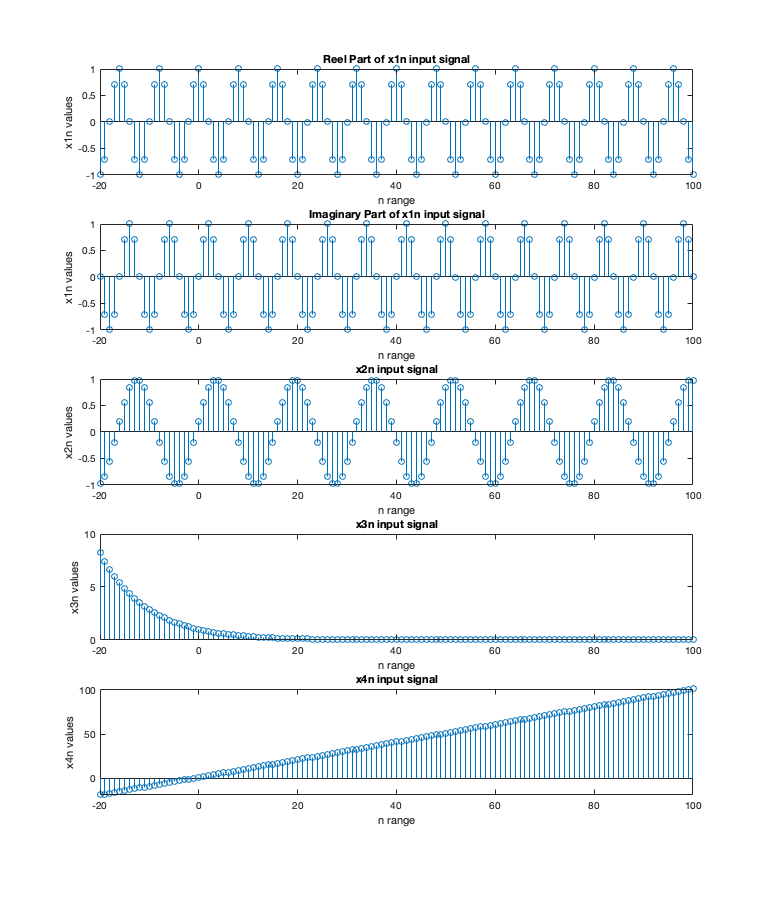

%3.4a


clf;
n=[-20:100];

x1n=exp(1j*(pi/4)*n);

x2n= sin(pi*n/8+pi/16);

x3n=(9/10).^n;

x4n= n+1;

figure(1);
figure('Position', [50, 50, 1024, 1200]);

subplot(5,1,1);stem(n,real(x1n));title('Reel Part of x1n input signal');xlabel('n range');ylabel('x1n values');

subplot(5,1,2);stem(n,imag(x1n));title('Imaginary Part of x1n input signal');xlabel('n range');ylabel('x1n values');

subplot(5,1,3);stem(n,x2n);title('x2n input signal');xlabel('n range');ylabel('x2n values');

subplot(5,1,4);stem(n,x3n);title('x3n input signal');xlabel('n range');ylabel('x3n values');

subplot(5,1,5);stem(n,x4n);title('x4n input signal');xlabel('n range');ylabel('x4n values');

(b). The **filter** command described in Tutorial 2.2 computes the output of the causal, LTI system described by a difference equation for a given input sequence. Define **a**

and **b** to specify the system shown in Eq. (3.3). Use these vectors and** filter **to compute the vectors $y_1,\ y_2,\ y_3$ and $y_4$, containing the output of the system specified

by Eq. (3.3) when the input is $x_1$ through  $x_4$, respectively. For each of the outputs you obtain, produce appropriately labeled plots of the portion of the outputs over the

interval $-20\le n \le 100$. For $y_1$, you will again need to plot the real and imaginary parts separately. Comparing your plots of inputs and outputs, indicate which of the input

signals are eigenfunctions of this LTI system.

Note: In both this part and the next part we will ignore the output samples over the interval $-20\le n \le -1$. These samples include transients due to the natural response

of the system because MATLAB is unable to work with infinitely long input signals. MATLAB assumes the input and output were zero before the values given in x. The

eigenfunction property of the system relates only to the steady-state solution. The signals and systems in this exercise have been chosen to insure the transients have

died out completely within 20 samples, so by restricting the interval examined to be $0\le n \le 100$, you are working with a portion of the output where the effect of the

natural response is insignificant.

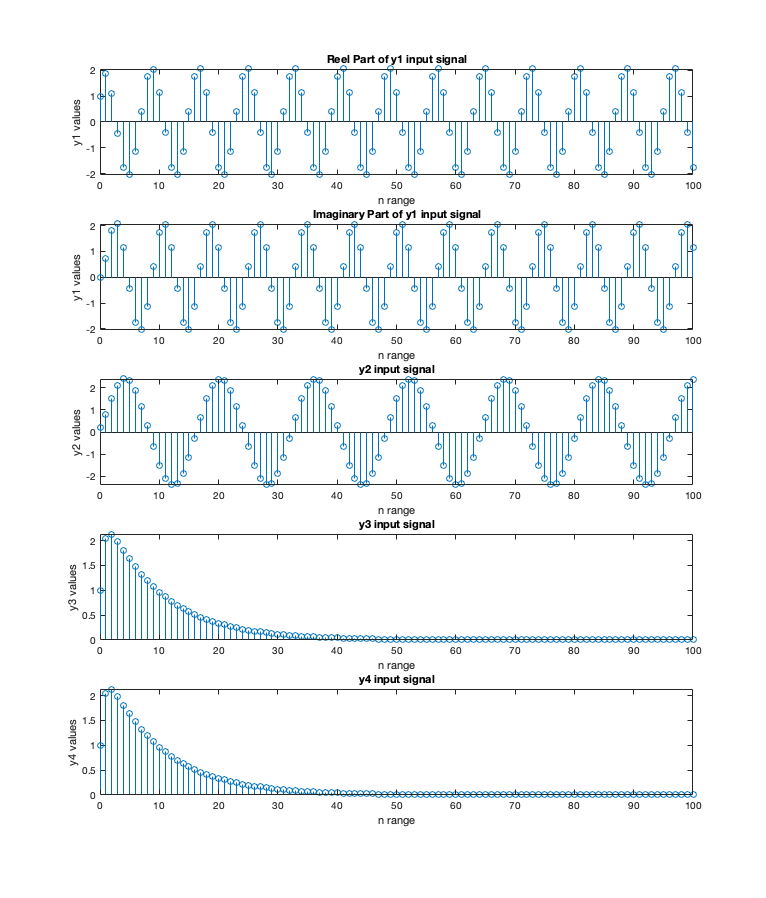

%3.4b

clf;
n1=[0:100];
x1=exp(j*(pi/4)*n1);

x2= sin(pi*n1/8+pi/16);

x3=(9/10).^n1;

x4= n1+1;
a1=[1 -0.25];

b1= [1 0.9];

y1=filter(b1,a1,x1);

y2=filter(b1,a1,x2);

y3=filter(b1,a1,x3);

y4=filter(b1,a1,x4);


figure(2);
figure('Position', [50, 50, 1024, 1200]);


subplot(5,1,1);stem(n1,real(y1));title('Reel Part of y1 input signal');xlabel('n range');ylabel('y1 values');

subplot(5,1,2);stem(n1,imag(y1));title('Imaginary Part of y1 input signal');xlabel('n range');ylabel('y1 values');

subplot(5,1,3);stem(n1,y2);title('y2 input signal');xlabel('n range');ylabel('y2 values');

subplot(5,1,4);stem(n1,y3);title('y3 input signal');xlabel('n range');ylabel('y3 values');

subplot(5,1,5);stem(n1,y3);title('y4 input signal');xlabel('n range');ylabel('y4 values');

(c). For this part, you will verify which of the inputs were eigenfunctions and compute the corresponding eigenvalues for those eigenfunctions. If the vectors **x** and **y** describe the

input and output sequences of a system, and the input sequence is an eigenfunction of the system, **y** should be equal to **x** scaled by a constant. This can be verified

by computing **H=y. /x,** which computes the ratio of the output to input sequence ateach time index. If the resulting vector **H** is a constant, the input signal was an

eigenfunction of the system. Compute $H_1$ through $H_4$ for each of the input/output signal pairs you obtained above, and produce appropriately labeled plots of **H** over

the interval $0\le n \le 100$ again. Again, $H_1$ will require separate plots for its real and imaginary parts. For the inputs which are eigenfunctions of the system, find the

 eigenvalue $H(z)$ from your plots or from the vector **H**.

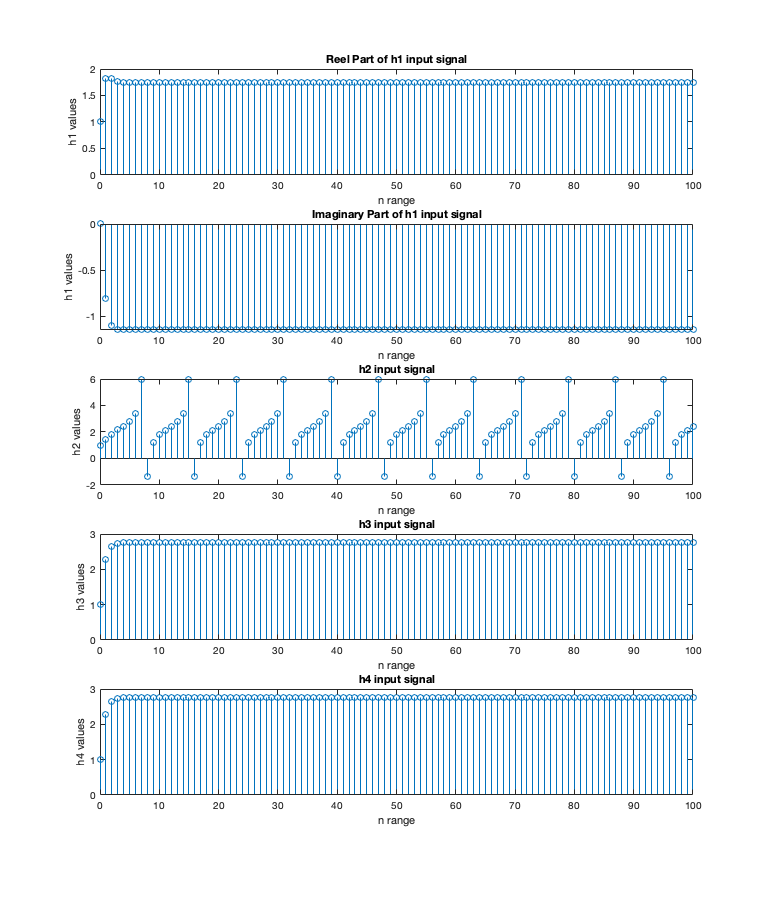

%3.4c


clf;

h1= y1./x1;

h2= y2./x2;

h3= y3./x3;

h4= y4./x4;


figure(3);
figure('Position', [50, 50, 1024, 1200]);


subplot(5,1,1);stem(n1,real(h1));title('Reel Part of h1 input signal');xlabel('n range');ylabel('h1 values');

subplot(5,1,2);stem(n1,imag(h1));title('Imaginary Part of h1 input signal');xlabel('n range');ylabel('h1 values');

subplot(5,1,3);stem(n1,h2);title('h2 input signal');xlabel('n range');ylabel('h2 values');

subplot(5,1,4);stem(n1,h3);title('h3 input signal');xlabel('n range');ylabel('h3 values');

subplot(5,1,5);stem(n1,h3);title('h4 input signal');xlabel('n range');ylabel('h4 values');

## 3.5 Synthesizing Signals with the Discrete-Time Fourier Series

The discrete-time Fourier series (DTFS) is a frequency-domain representation for periodic discrete-time sequences. The synthesis and analysis equations for the DTFS are given by

Eqs. (3.1) and (3.2). This exercise contains three sets of problems to give you practice working with these equations. The Basic Problems allow you to synthesize a very simple

periodic discrete-time signal from its DTFS coefficients. In the Intermediate Problems, you will both analyze a set of periodic discrete-time signals to obtain their DTFS coefficients,

and construct one of these signals by adding in a few coefficients at a time. For the Advanced Problem, you will write a function to find the DTFS coefficients of an arbitrary periodic

discrete-time signal from one period of samples.

**Basic Problems**

In these problems, you will synthesize a periodic discrete-time signal with period $N=5$ and the following DTFS coefficients

                                        
$$a_0=1, \ a_2=a^* _{-2}=e^{j\pi/4}, \ a_4=a^* _{-4}=2e^{j\pi/3}$$


(a). Based on the DTFS coefficients, do you expect x[n] to be complex-valued, purely real, or purely imaginary? Why?

**3.5a Analysis**

It is given:

        
$$N=5, \ a_0=1$$


        
$$a_2=e^{j\pi/4}=cos(\pi/4)+jsin(\pi/4)=\frac{1+j}{\sqrt2}$$


        
$$a_{-2}^*=e^{j\pi/4} \Longrightarrow  a_{-2}=e^{-j\pi/4}=cos(\pi/4)-jsin(\pi/4)=\frac{1-j}{\sqrt2}$$


        
$$a_4=2e^{j\pi/3}=2cos(\pi/3)+2jsin(\pi/3)=1 +j\sqrt3$$


        
$$a_{-4}^*=2e^{j\pi/3} \Longrightarrow a_{-4}=2e^{-j\pi/3}=2cos(\pi/3)-2jsin(\pi/3)=1 -j\sqrt3$$


        
$$w_0=\frac{2\pi}{N}=\frac{2\pi}{5}$$


Then using a Fourier series coefficients we can express $x(t)$, then, using a Fourier coefficients we can express $x[n]$:

 
$$x[n] =\sum_{k=0}^{N-1} a_ke^{jkw_0n}$$


                
$$=a_{-4}e^{-j4\frac{2\pi}{5}n }+a_{-2}e^{-j2 \frac{2\pi}{5}n }+a_0+a_{2}e^{j2 \frac{2\pi}{5}n }+a_{4}e^{j4 \frac{2\pi}{5}n }\\

= (1-j\sqrt3 )e^{-j\frac{8\pi}{5}n} +  \left(\frac{1-j}{\sqrt2} \right) e^{-j\frac{4\pi}{5}n}+1+ \left(\frac{1+j}{\sqrt2} \right) e^{j\frac{4\pi}{5}n}+ (1+j\sqrt3 )e^{j\frac{8\pi}{5}n} \\

= 1+ \left ( e^{j\frac{8\pi}{5}n}  + e^{-j\frac{8\pi}{5}n}  \right ) + j\sqrt3 \left( e^{j\frac{8\pi}{5}n}  - e^{-j\frac{8\pi}{5}n}    \right) +  \frac{1+j}{\sqrt2} \left (  e^{j\frac{4\pi}{5}n} +e^{-j\frac{4\pi}{5}n}  \right )
+ \frac{j}{\sqrt2} \left (  e^{j\frac{4\pi}{5}n} -e^{-j\frac{4\pi}{5}n}  \right )
$$


 Now we can apply Euler's identity:

                
$$cos(x) = \frac{e^{jx}+e^{-jx}}{2}\\
sin(x)= \frac{e^{jx}-e^{-jx}}{2j}$$


Then, $x[n]$ can be written as:

            
$$x[n]= 1+ 2cos(\frac{8\pi}{5}n)+j\sqrt3.2jsin(\frac{8\pi}{5}n ) + \frac{2}{\sqrt2}cos(\frac{4\pi}{5}n)
+ \frac{j}{\sqrt2}.2j sin(\frac{4\pi}{5}n) \\

= 1+2cos(\frac{8\pi}{5}n)-2\sqrt3sin(\frac{8\pi}{5}n)+ \sqrt2cos(\frac{4\pi}{5}n)-\sqrt2sin(\frac{4\pi}{5}n)$$


Now, we can use following identities:

        
$$2= 4.cos(\pi/3)\\
2\sqrt3=4.sin(\pi/3)\\
\sqrt2 = 2.cos(\pi/4)=2.sin(\pi/4)$$


Then We have :

        
$$x[n]= 1 + 4cos(\pi/3)cos(\frac{8\pi}{5}n)- 4sin(\pi/3)sin(\frac{8\pi}{5}n)+  2cos(\pi/4)cos(\frac{4\pi}{5}n) - 2sin(\pi/4)sin(\frac{4\pi}{5}n) \\

=1+ 4\left(  cos(\pi/3)cos(\frac{8\pi}{5}n )- sin(\pi/3)sin(\frac{8\pi}{5}n)      \right) + 2 \left( cos(\pi/4)cos(\frac{4\pi}{5}n) -   sin(\pi/4)sin(\frac{4\pi}{5}n)   \right)$$


We can apply trigonometric identities as follows:

            
$$cos(x)cos(y)-sin(x)sin(y)= cos(x+y)$$


Then $x[n]$ can be written as:

            
$$x[n] = 1+ 2cos(\frac{4\pi}{5}n+ \frac{\pi}{4} ) + 4cos(\frac{8\pi}{5}n+ \frac{\pi}{3} ) $$


For that reason it is purely real

(b). Using the DTFS coefficients given above, determine the values of **a0** through **a4** and specify a vector **a** containing these values.

In a discrete-time Fourier series, the coefficients $a_k$ are coresponses of the harmonics at certain frequences. When we represent them in a vector, it needs to follow the sequency (or order) in accordancy to the frequence domain.

        
$$a_k = (a_0, a_2,a_{-2},  a_4,a_{-4}  )$$


We have th vector as :

                
$$a =[ 1,0, e^{j\pi /4,0, e^{\pi/3}} ]$$


(c). Using the vector **a** of DTFS coefficients and the synthesis equation, define a new vector x containing one period of the signal $x[n]$ for  $0\le n\le 4$. You can either write

out the summation explicitly or you may find it helpful to use a **for** loop. Generate an appropriately labeled plot of $x[n]$ for $0\le n\le 4$ using **stem**. Was your prediction

in Part (a) correct? Note that if you predicted a purely imaginary or real signal, it may still have a very small $(< 10^{-10})$ nonzero real or imaginary part due to roundoff

errors. If this is the case, set this part to be zero using **real** or **imag** as appropriate before making your plot.

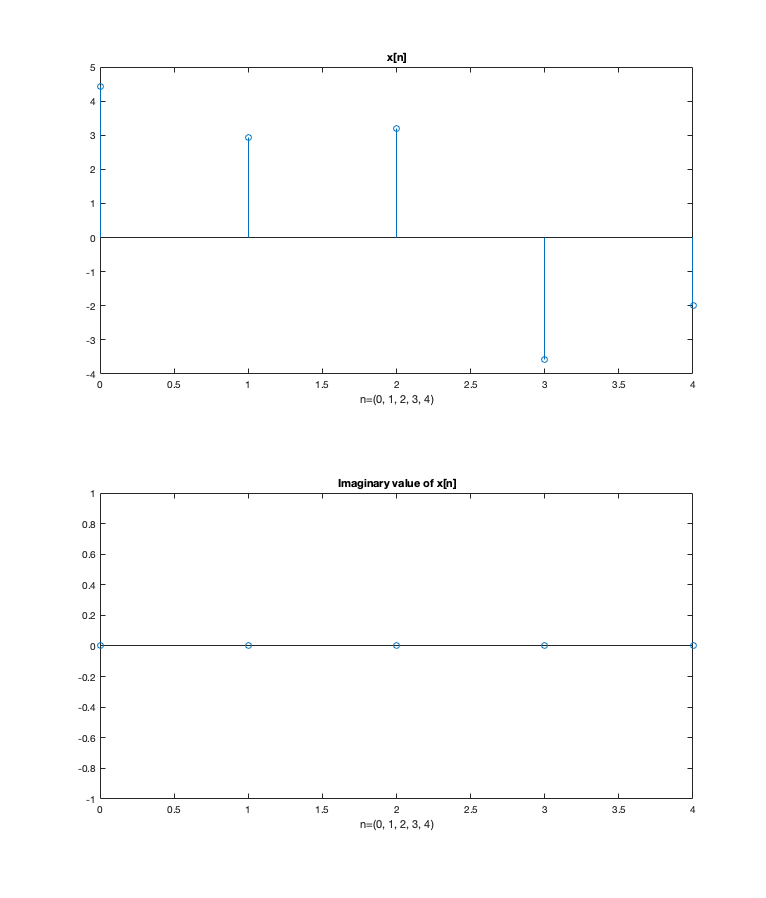

%3.5c

clf;
figure(4);
n=[0:4];
x=n*0;

% I forgot the last version of xn and go with a_k values for that reason
% results were similiar but there was a small mistake and I corrected

x= 1+ 2*cos(4*pi.*n/5+pi/4) + 4*cos(8*pi.*n/5+pi/3);


figure(4);

subplot(2,1,1);stem(n,x); title('x[n]'); xlabel('n=(0, 1, 2, 3, 4)');
subplot(2,1,2);stem(n, imag(x)); title('Imaginary value of x[n]'); xlabel('n=(0, 1, 2, 3, 4)');

## 3.6 Properties of the Continuous-Time Fourier Series

This exercise examines properties of the continuous-time Fourier series (CTFS) representation for periodic continuous-time signals. 

Consider the signal

                                            $x_1(t)= cos(\omega_0 t) + sin(2\omega_0t),$                                    (3.7)

where $\omega_0=2\pi$. To evaluate this signal in MATLAB, use the time vector

>> t=linspace(-1,1,1000);

which creates a vector of 1000 time samples over the region $-1\le t\le 1.$

## **lntermediate Problems**

(a). What is the smallest period, **T**, for which x $x_1(t)=x_1(t+T)$? Analytically find the coefficients of the CTFS for $x_1(t)$ using this value of **T**.

**3.6a Analysis**


$$x_1(t)= cos(\omega_0 t) + sin(2\omega_0t)  \Longrightarrow x_1(t) = cos(2\pi t)+ sin(4\pi t) \\


 \ cos(2\pi t) = \frac{1}{T} e^{2\pi t} +\frac{1}{T} e^{-2\pi t} ,\ \ sin(4\pi t) = \frac{1}{jT} e^{4\pi t} - \frac{1}{jT} e^{-4\pi t} $$
  

So that nonzero FS coefficients of $x_1(t)$ are :

        
$$a_1 =a_{-1}= 1/T \ and \  \  b_1 = 1/jT,\ \ b_{-1}= 1/jT$$


**Note: The function sum of cosinuse and sine, for that reason, I calculated separately.**

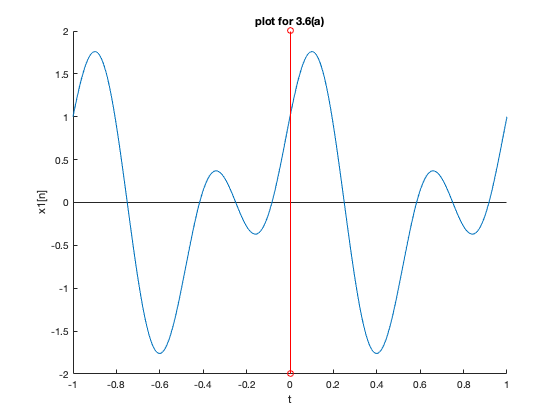

clf;
t=linspace(-1,1,1000);
x1 = cos(2*pi.*t) + sin(4*pi.*t);
figure(5);
hold on;
plot(t,x1); xlabel('t'); ylabel('x1[n]'); title('plot for 3.6(a)');
stem(0,2,'r');
stem(0,-2,'r');
hold off;

(b). Consider the signal $y(t)=x_1(t)+x_1(-t)$. Using the time-reversal and conjugation properties of the CTFS, determine the coefficients for the CTFS of  $y(t)$.

**3.6b Analysis**

$cos(-t)= cos(t)$ and $sin(-t)= - sin(t)$.

For that reason $a_1 \ and \ a_{-1}$ will not change. In addition, $b_1 \  and\ b_{-1}$ will be multiple by minus.

(c). Plot the signal $y(t)$ over $-1\le t\le 1$. What type of symmetry do you expect? Can you explain what you see in terms of the symmetry properties of the CTFS?

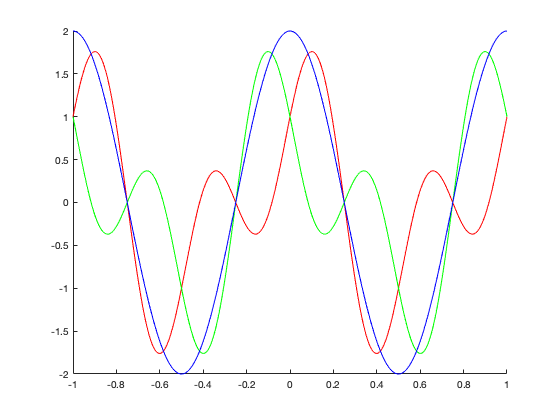

%3.6c
w0=2*pi;
t=linspace(-1,1,1000);

% the mistake was I used * instead of .* and I didn't plot everyhing
% because of the questions for that reason I add the other plots too
x1=cos(w0.*t)+sin(2*w0.*t);
x1r=cos(w0.*(-t))+sin(2*w0.*(-t));
yt= x1+x1r;
figure(6);
hold on;
plot(t,x1,'r');
plot(t,x1r,'g');

plot(t,yt,'b');

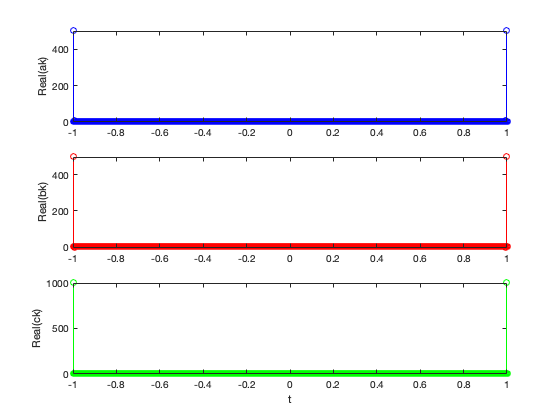

% I couldn't be sure for that reason I didn't add this part in the first submission, I wasn't sure because of the output. 
% I also change the variables name and make a,b,c to make evaulation faster

N=1;
a=fft(x1)/N;
b=fft(x1r)/N;
c=fft(yt)/N;
figure(7);
subplot(3,1,1); stem(t,real(a),'b'); ylabel('Real(ak)');
subplot(3,1,2); stem(t,real(b),'r'); ylabel('Real(bk)');
subplot(3,1,3); stem(t,real(c),'g'); ylabel('Real(ck)'); xlabel('t');

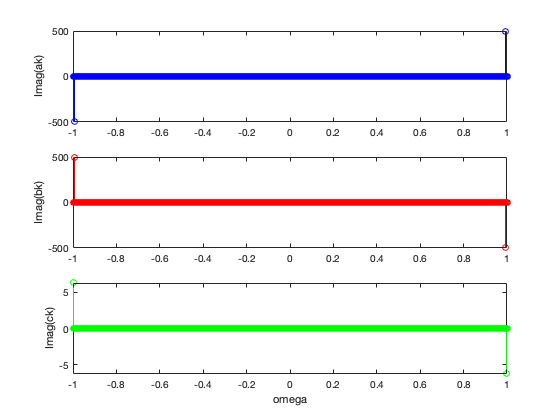

figure(8);
subplot(3,1,1); stem(t,imag(a),'b'); ylabel('Imag(ak)');
subplot(3,1,2); stem(t,imag(b),'r'); ylabel('Imag(bk)');
subplot(3,1,3); stem(t,imag(c),'g'); ylabel('Imag(ck)'); xlabel('omega')

(d). Consider the signal $z(t) = x_1(t)-x_1^*(-t)$. Using the time-reversal and conjugation properties of the CTFS, determine the coefficients for the CTFS of $z(t)$.

**3.6d Analysis**

The ime-reversal and conjugation properties (Eq 3.65, main Textbook)

            if $x_1(t) \leftrightarrow a_k ,\ then \ x_1(t)* \leftrightarrow a^* _{-k}$ 

  and by (Eq 3.66, main Textbook)

            
$$x^*_1(-t) \leftrightarrow b_k=a_k^*=a_{-k}$$


Therefore $z(t)$ has the Fourier Series $c_k$ as:

            
$$c_k=a_k-a_{-k}$$


Since $x_1(t)$ is real and even $a_k=a_{-k}$, for that reason $c_k = 0$.

(e). Plot the signal $z(t)$ over $-1\le t\le 1$. What type of symmetry do you expect to see? Can you explain what you see in terms of the symmetry properties of the CTFS?

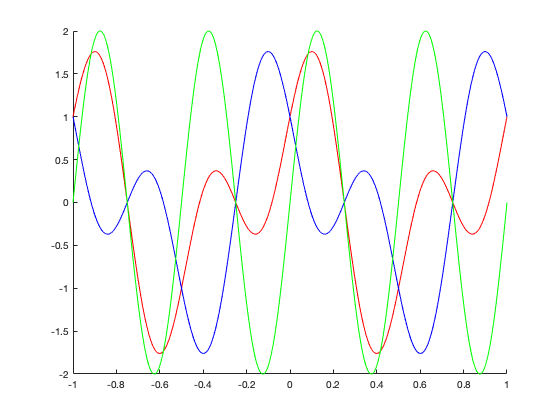

%3.6e 

zt= x1-x1r;
figure(9);
hold on;
plot(t,x1,'r');
plot(t,x1r,'b');
plot(t,zt,'g');

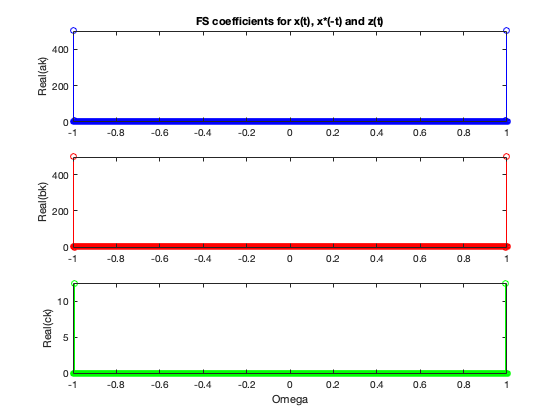

c=fft(zt)/N;
figure(10);
subplot(3,1,1); stem(t,real(a),'b'); ylabel('Real(ak)');
title('FS coefficients for x(t), x*(-t) and z(t)');
subplot(3,1,2); stem(t,real(b),'r'); ylabel('Real(bk)');
subplot(3,1,3); stem(t,real(c),'g'); ylabel('Real(ck)');
xlabel('Omega');

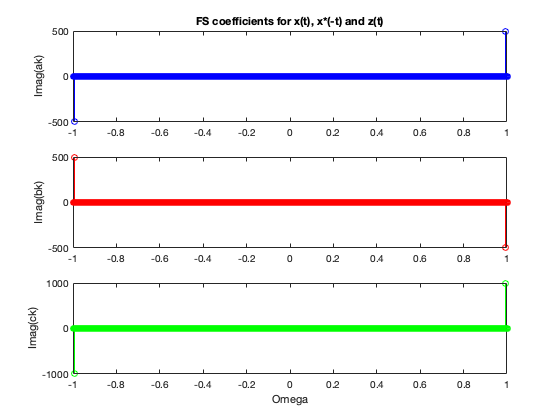

figure(11);
subplot(3,1,1); stem(t,imag(a),'b'); ylabel('Imag(ak)');
title('FS coefficients for x(t), x*(-t) and z(t)');
subplot(3,1,2); stem(t,imag(b),'r'); ylabel('Imag(bk)');
subplot(3,1,3); stem(t,imag(c),'g'); ylabel('Imag(ck)');
xlabel('Omega');

(f). Repeat Parts (a)-(e) using

                                                             $x_2(t)= cos(\omega_0t)+isin(2\omega_0 t)$                                                                            (3.8)

Note that $x_2(t)$ is complex. When plotting $x_2(t)$, $y(t)$, and $z(t)$, be sure to plot the real and imaginary parts separately and take note of the symmetry that you see in

each.

**3.6f Analysis**


$$x_1(t)= cos(\omega_0 t) + jsin(2\omega_0t)  \Longrightarrow x_1(t) = cos(2\pi t)+ jsin(4\pi t) \\


 \ cos(2\pi t) = \frac{1}{T} e^{2\pi t} +\frac{1}{T} e^{-2\pi t} ,\ \ jsin(4\pi t) = j \cdot \frac{1}{jT} e^{4\pi t} -j \cdot \frac{1}{jT} e^{-4\pi t}  =   \frac{1}{T} e^{4\pi t} - \frac{1}{T} e^{-4\pi t}$$
  

So that nonzero FS coefficients of $x_1(t)$ are :

        
$$a_1 =a_{-1}= 1/T \ and \  \  b_1 = 1/T,\ \ b_{-1}= 1/T$$


$cos(-t)= cos(t)$ and $sin(-t)= - sin(t)$.

For that reason $a_1 \ and \ a_{-1}$ will not change. In addition, $b_1 \  and\ b_{-1}$ will be multiple by minus.

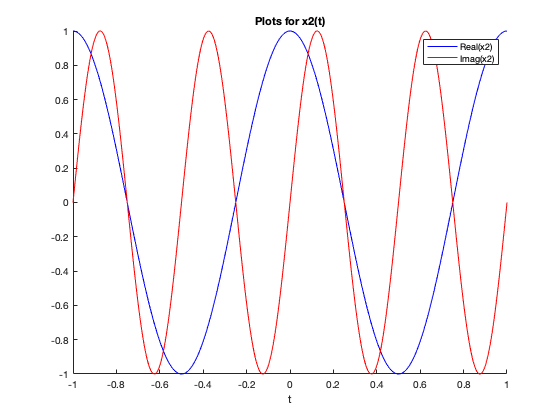

%3.6f
% * ==> .* and couple difference caused by misreading.
% I also change plotting style make the same with yours.

clf;
x2=cos(w0.*t)+1j*sin(2*w0.*t);
x2t = cos(2*pi.*(-t) + 1j*sin(4*pi.*(-t)));
x2r=cos(w0.*(-t))-1j*sin(2*w0.*(-t));


figure(12);
hold on;
plot(t,real(x2),'b');
plot(t,imag(x2),'r');
xlabel('t'); title('Plots for x2(t)'); legend('Real(x2)','Imag(x2)');
hold off;

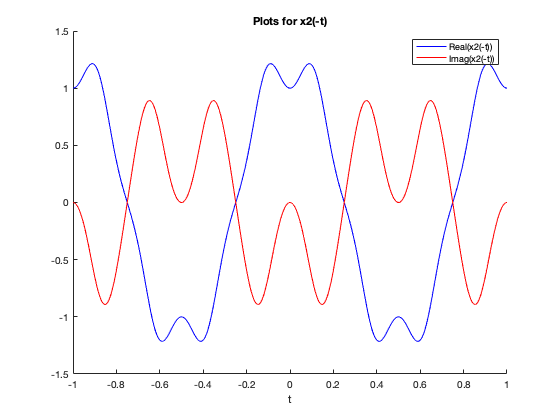

clf;
figure(13);
hold on;
plot(t,real(x2t),'b');
plot(t,imag(x2t),'r');
xlabel('t'); title('Plots for x2(-t)'); legend('Real(x2(-t))','Imag(x2(-t))');
hold off;

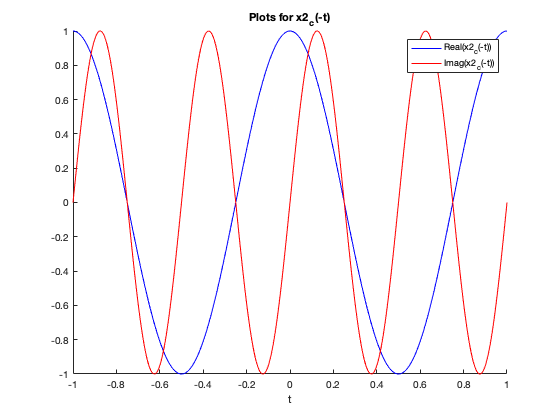

clf;
figure(13);
hold on;
plot(t,real(x2r),'b');
plot(t,imag(x2r),'r');
xlabel('t'); title('Plots for x2_c(-t)'); 
legend('Real(x2_c(-t))','Imag(x2_c(-t))');
hold off;

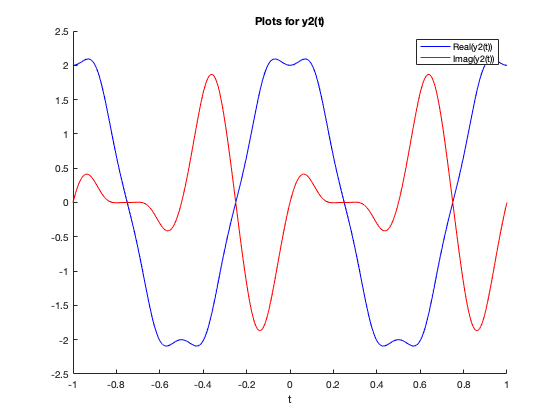

clf;
y2 = x2 + x2t;
figure(14);
hold on;
plot(t,real(y2),'b');
plot(t,imag(y2),'r');
xlabel('t'); title('Plots for y2(t)'); 
legend('Real(y2(t))','Imag(y2(t))');
hold off;

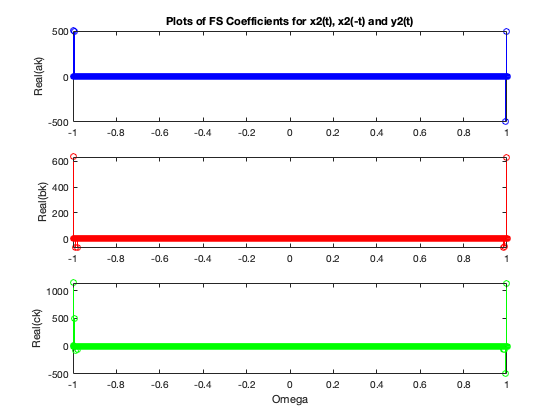

clf;
N=1;
a2=fft(x2);
b2=fft(x2t);
c2=fft(y2);
figure(15);
subplot(3,1,1); stem(t,real(a2),'b'); ylabel('Real(ak)');
title('Plots of FS Coefficients for x2(t), x2(-t) and y2(t)')
subplot(3,1,2); stem(t,real(b2),'r'); ylabel('Real(bk)');
subplot(3,1,3); stem(t,real(c2),'g'); ylabel('Real(ck)'); xlabel('Omega');

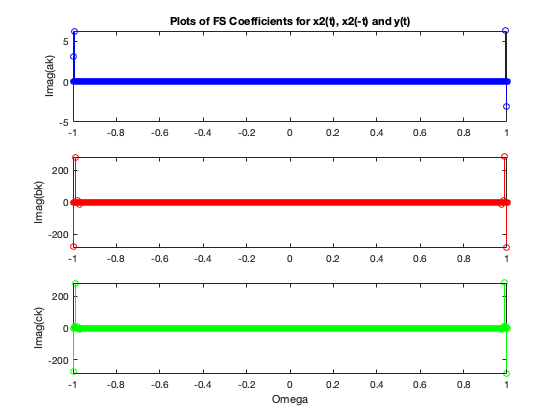

clf;
figure(16);
subplot(3,1,1); stem(t,imag(a2),'b'); ylabel('Imag(ak)');
title('Plots of FS Coefficients for x2(t), x2(-t) and y(t)')
subplot(3,1,2); stem(t,imag(b2),'r'); ylabel('Imag(bk)');
subplot(3,1,3); stem(t,imag(c2),'g'); ylabel('Imag(ck)'); xlabel('Omega');

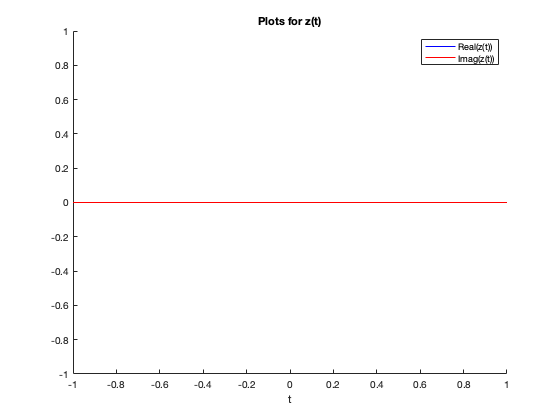

clf;
z2 = x2 - x2r;
figure(17);
hold on;
plot(t,real(z2),'b');
plot(t,imag(z2),'r');
xlabel('t'); title('Plots for z(t)'); legend('Real(z(t))','Imag(z(t))');

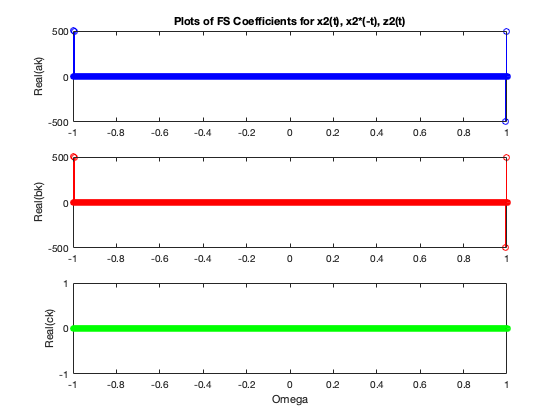

clf;
a2=fft(x2);
b2=fft(x2r);
c2=fft(z2);
figure(18);
subplot(3,1,1); stem(t,real(a2),'b'); ylabel('Real(ak)');
title('Plots of FS Coefficients for x2(t), x2*(-t), z2(t)')
subplot(3,1,2); stem(t,real(b2),'r'); ylabel('Real(bk)');
subplot(3,1,3); stem(t,real(c2),'g'); ylabel('Real(ck)'); xlabel('Omega');

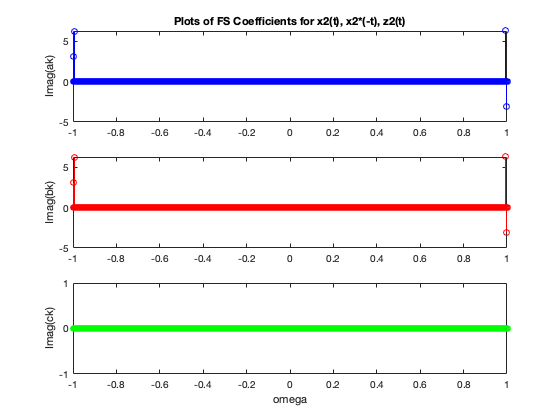

clf;

figure(19);
subplot(3,1,1); stem(t,imag(a2),'b'); ylabel('Imag(ak)');
title('Plots of FS Coefficients for x2(t), x2*(-t), z2(t)')
subplot(3,1,2); stem(t,imag(b2),'r'); ylabel('Imag(bk)');
subplot(3,1,3); stem(t,imag(c2),'g'); ylabel('Imag(ck)'); xlabel('omega')